clear all
close all

## training Stage

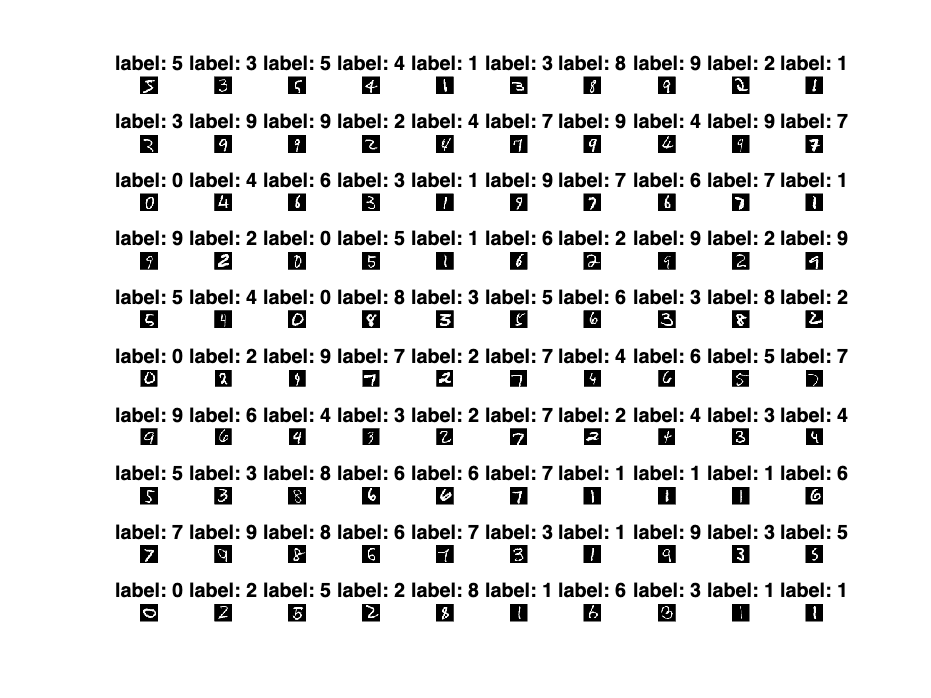

% Loading labels and examples of handwritten digits from MNIST Dataset
%Since they are too many of them, to make it usable for this practical we
%will be taking one out of many images (one out of 'sampling'). This is
%done by using the variable sampling>1
sampling=50;
images = loadMNISTImages('train-images',sampling);
labels = loadMNISTLabels('train-labels',sampling);

% For visualization purposes, we display the first 100 images
figure
for i=1:100
    
    % As you can notice by the size of the matrix image, each digit image
    % has been transform into a long feature vector to be fed in a machine
    % learning algorithm.
    
    %To visualise or recompose the image again, we need to revert that
    %process in its 28x28 image format
    Im = reshape(images(i,:),28,28);
    subplot(10,10,i), imshow(Im), title(['label: ',num2str(labels(i))])
    
end

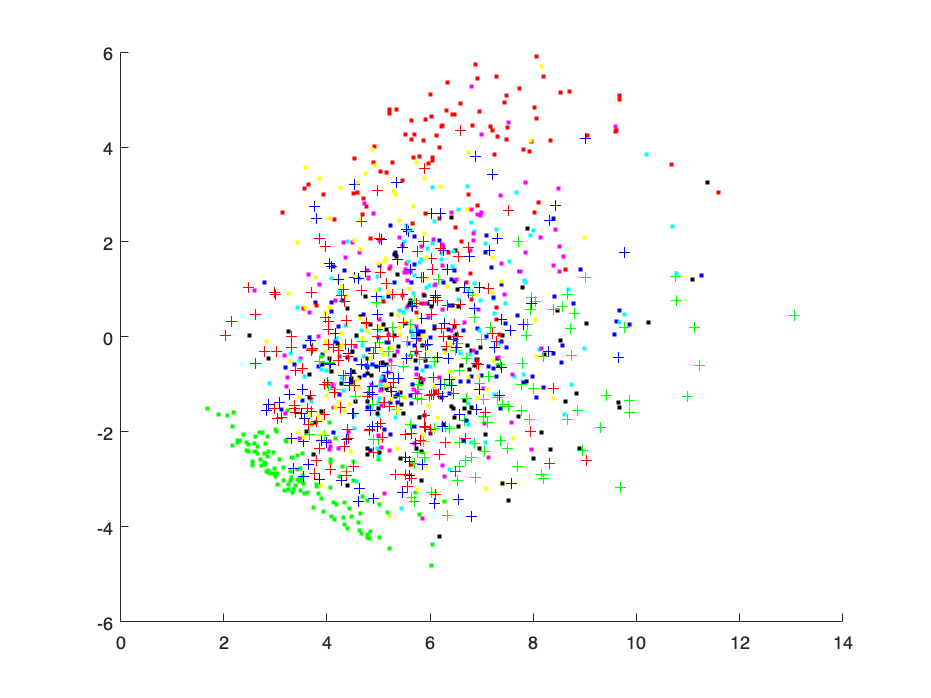


%Supervised training function that takes the examples and infers a model
modelNN = NNtraining(images, labels);


% It is difficult for humans to visualise the full space of digits, since they have more than 700 dimension.
% In order to make it more human friendly and understand how difficult is
% the problem, i.e. how close or far away are the different classes, we can
% apply dimenisonality reduction (we will see this in our last lectures), which will give us the most relevant
% dimension to observe
[U,S,X_reduce] = pca(images,3);

figure, hold on
colours= ['r.'; 'g.'; 'b.'; 'k.'; 'y.'; 'c.'; 'm.'; 'r+'; 'g+'; 'b+'; 'k+'; 'y+'; 'c+'; 'm+'];
count=0;
for i=min(labels):max(labels)
    count = count+1;
    indexes = find (labels == i);
    plot3(X_reduce(indexes,1),X_reduce(indexes,2),X_reduce(indexes,3),colours(count,:))
end

## testing

Loading testing labels and testing examples of handwritten digits from MNIST Dataset It is very important that this images are different from the ones used in training or our results will not be reliable

images = loadMNISTImages('test-images',sampling);
labels = loadMNISTLabels('test-labels',sampling);
indexesZeros = find (labels == 0);
indexesOnes = find (labels == 1);

images= [images(indexesZeros,:); images(indexesOnes,:)];
labels= [labels(indexesZeros); labels(indexesOnes)];


%For each testing image, we obtain a prediction based on our trained model
for i=1:size(images,1)
    
    testnumber= images(i,:);
    
    classificationResult(i,1) = NNTesting(testnumber, modelNN);
    
end

## Evaluation

% Finally we compared the predicted classification from our mahcine
% learning algorithm against the real labelling of the esting image
comparison = (labels==classificationResult);

%Accuracy is the most common metric. It is defiend as the numebr of
%correctly classified samples/ the total number of tested samples

sum(comparison)

ans = 35

length(comparison)

ans = 37

Accuracy = double(sum(comparison)/length(comparison))

Accuracy = 0.9459

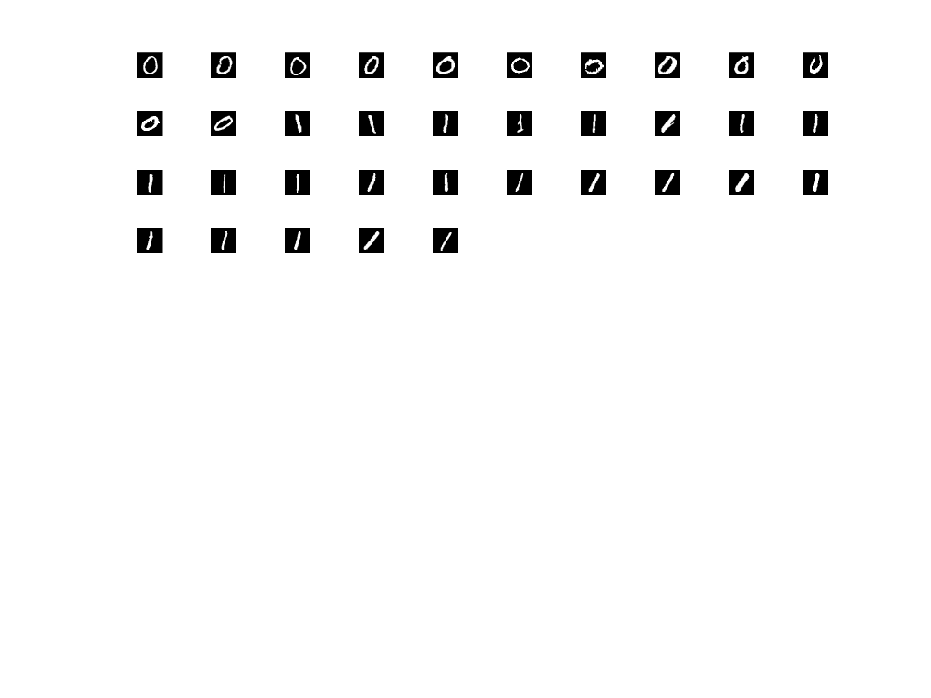




%We display 100 of the correctly classified images
figure
title('Correct Classification')
count=0;
i=1;
while (count<100)&&(i<=length(comparison))
    
    if comparison(i)
        count=count+1;
        subplot(10,10,count)
        Im = reshape(images(i,:),28,28);
        imshow(Im)
    end
    
    i=i+1;
    
end

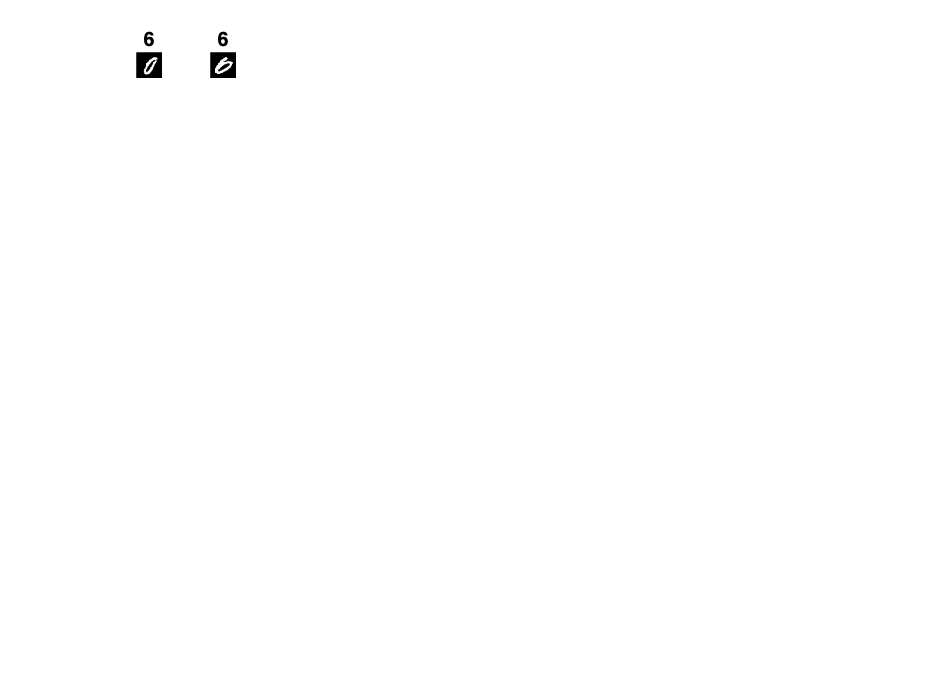



%We display 100 of the incorrectly classified images
figure
title('Wrong Classification')
count=0;
i=1;
while (count<100)&&(i<=length(comparison))
    
    if ~comparison(i)
        count=count+1;
        subplot(10,10,count)
        Im = reshape(images(i,:),28,28);
        imshow(Im)
        title(num2str(classificationResult(i)))
    end
    
    i=i+1;
    
end

save detectorModelNN modelNN